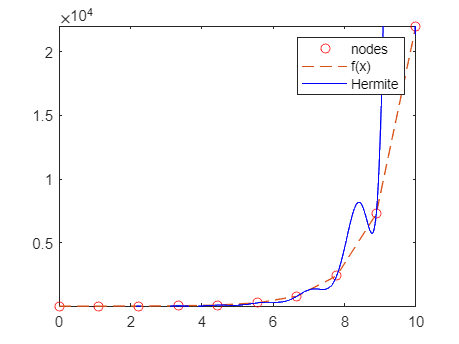

%Hermite interpolation

n=10;
a=0;
b=10;
x_nodes= linspace(a,b,n);
f=@(x) exp(x);
df=@(x) exp(x);

y=f(x_nodes);
dy=df(x_nodes);

n_interpolants=1000;
x_interpolants=linspace(x_nodes(1),x_nodes(end),n_interpolants);




h=@(x,i) (x-x_nodes(i)).*(Lagrange_polynomaials(x_nodes,x,i)).^2;
dh=@(x,i) (1-(2*Diff_lagrange(x_nodes,x,i)*(x-x_nodes(i))))*(Lagrange_polynomaials(x_nodes,x,i)).^2;


for i=1:n_interpolants
    h_sum=0;
    dh_sum=0;
    for j=1:n
        h_sum= h_sum+(y(j)*h(x_interpolants(i),j));
        dh_sum=dh_sum+(dy(j)*dh(x_interpolants(i),j));
    end
    H(i)=h_sum+dh_sum;
end



plot(x_nodes,y,'ro')
hold on
plot(x_nodes,y,'--')
plot(x_interpolants,H,'b')

hold off
ylim([f(x_interpolants(1)) f(x_interpolants(end))])
legend('nodes','f(x)','Hermite')